Data = Task1{:, 1}; % Extract the data from the table as a numeric vector.

% Calculate the mean of the data.
Avg = mean(Data);

% Display the mean.
disp(Avg)

   14.5002



Med = median(Data)

Med = 14.5300

disp(Med)

   14.5300



Std = std(Data)

Std = 0.4030

disp(Std)

    0.4030



Var = var(Data)

Var = 0.1624

disp(Var)

    0.1624



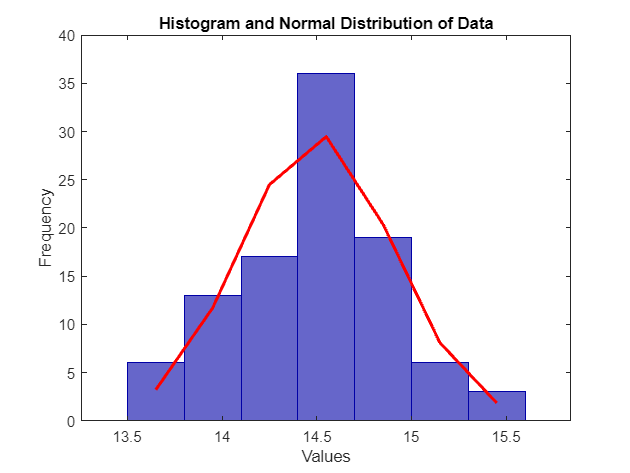

% Create a histogram of the data with dark blue bars.
histogram(Data, 'FaceColor', [0, 0, 0.65]); % Dark blue color specified as RGB triplet

% Get the histogram bin counts and bin edges.
[counts, edges] = histcounts(Data);

% Calculate the bin widths.
binWidths = diff(edges);

% Calculate the bin centers.
binCenters = edges(1:end-1) + binWidths / 2;

% Fit a normal distribution curve to the data.
hold on;
mu = mean(Data);
sigma = std(Data);
pdf_values = (1 / (sigma * sqrt(2 * pi))) * exp(-((binCenters - mu).^2) / (2 * sigma^2));
bar(binCenters, counts, 'BarWidth', 1, 'FaceColor', 'none', 'EdgeColor', [0, 0, 0.65]); % Dark blue edge color specified as RGB triplet
plot(binCenters, pdf_values * sum(counts) * binWidths(1), 'r', 'LineWidth', 2); % Scale the PDF to match the count
hold off;

% Add labels and a title to the plot.
xlabel('Values');
ylabel('Frequency');
title('Histogram and Normal Distribution of Data');

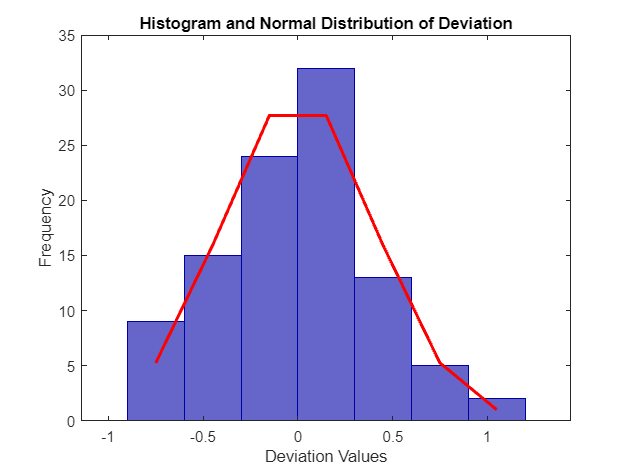

% Calculate the mean of the data.
meanValue = mean(Data);

% Calculate the deviations from the mean.
deviations = Data - meanValue;

% Create a histogram of the deviation values with dark blue bars.
histogram(deviations, 'FaceColor', [0, 0, 0.65]); % Dark blue color specified as RGB triplet

% Get the histogram bin counts and bin edges.
[counts, edges] = histcounts(deviations);

% Calculate the bin widths.
binWidths = diff(edges);

% Calculate the bin centers.
binCenters = edges(1:end-1) + binWidths / 2;

% Fit a normal distribution curve to the deviation data.
hold on;
mu = mean(deviations);
sigma = std(deviations);
pdf_values = (1 / (sigma * sqrt(2 * pi))) * exp(-((binCenters - mu).^2) / (2 * sigma^2));
bar(binCenters, counts, 'BarWidth', 1, 'FaceColor', 'none', 'EdgeColor', [0, 0, 0.65]); % Dark blue edge color specified as RGB triplet
plot(binCenters, pdf_values * sum(counts) * binWidths(1), 'r', 'LineWidth', 2); % Scale the PDF to match the count
hold off;

% Add labels and a title to the plot.
xlabel('Deviation Values');
ylabel('Frequency');
title('Histogram and Normal Distribution of Deviation');

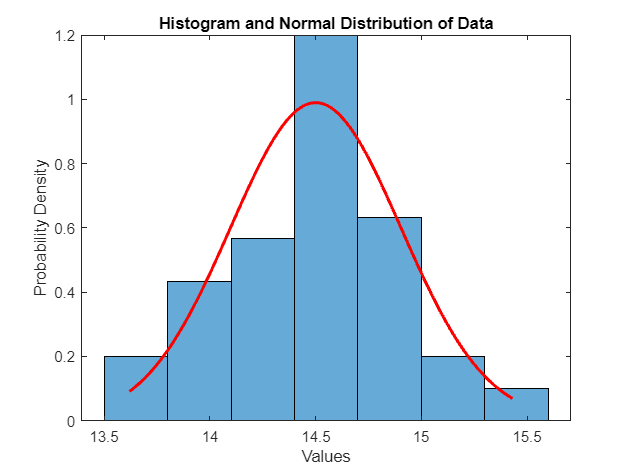

% Assuming 'Data' is a double variable (replace 'Data' with your actual variable name).% Create a histogram of the data.
histogram(Data, 'Normalization', 'pdf');

% Fit a normal distribution curve to the data.
hold on;
mu = mean(Data);
sigma = std(Data);
x = min(Data):0.01:max(Data); % Adjust the step size as needed.
pdf_values = (1 / (sigma * sqrt(2 * pi))) * exp(-((x - mu).^2) / (2 * sigma^2));
plot(x, pdf_values, 'r', 'LineWidth', 2);
hold off;

% Add labels and a title to the plot.
xlabel('Values');
ylabel('Probability Density');
title('Histogram and Normal Distribution of Data');

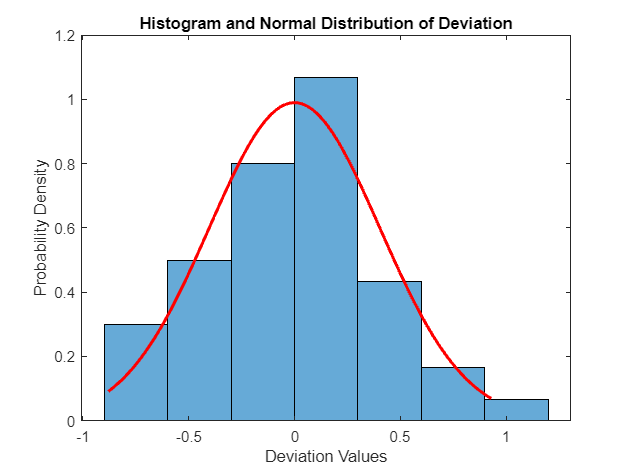

% Calculate the mean of the data.
meanValue = mean(Data);

% Calculate the deviations from the mean.
deviations = Data - meanValue;

% Create a histogram of the deviation values.
histogram(deviations, 'Normalization', 'pdf');

% Fit a normal distribution curve to the deviation data.
hold on;
mu = mean(deviations);
sigma = std(deviations);
x = min(deviations):0.01:max(deviations); % Adjust the step size as needed.
pdf_values = (1 / (sigma * sqrt(2 * pi))) * exp(-((x - mu).^2) / (2 * sigma^2));
plot(x, pdf_values, 'r', 'LineWidth', 2);
hold off;

% Add labels and a title to the plot.
xlabel('Deviation Values');
ylabel('Probability Density');
title('Histogram and Normal Distribution of Deviation');